## Mixed Sensitivity Design

Using LQ (L2) state feedback for a resonant controller

clear

Linearise the Extended Plant from Simulink

P1 = M2S(linmod('model_plant'));
W1z = tf(1,1);
W1a = M2S(linmod('model_w1a'));
W1b = M2S(linmod('model_w1b'));

W1ab = [W1a*10;W1b*50];
W1 = [W1z*0;W1ab];
% extended plant
Px = W1 * P1

Px =
 
  A = 
         x1    x2    x3    x4
   x1     0     0     0    10
   x2     0   -10  -100  5000
   x3     0   100     0     0
   x4     0     0     0    -1
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   1
 
  C = 
       x1  x2  x3  x4
   y1   0   0   0   0
   y2   1   0   0   0
   y3   0   1   0   0
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.



Design the LQ State Feedback Controller

% unity weights (weighting is in W)
Q = Px.C'*Px.C;
R = 1;
K = lqr(Px,Q,R)

K =     1.0000    0.1909   -0.7812   42.9264


(k_i k_r1 k_r2 k_p)

Construct the Transfer Function of the Controller

% insert the weights
W1y = [W1ab;0];
W1y.C = eye(size(W1y.C));
Kx = K * [W1y;1];
% analyse results
zpk(tf(Kx))

ans =
 
  -42.926 (s+2.845) (s^2 + 29.62s + 819)
  --------------------------------------
           s (s^2 + 10s + 1e04)
 
Continuous-time zero/pole/gain model.



K1=zpk(tf(K*diag([1 0 0 1])*[W1y;1]))

K1 =
 
  42.926 (s+0.233)
  ----------------
         s
 
Continuous-time zero/pole/gain model.



K2=zpk(tf(K*diag([0 1 1 0])*[W1y;1]))

K2 =
 
   954.26 (s-409.3)
  ------------------
  (s^2 + 10s + 1e04)
 
Continuous-time zero/pole/gain model.



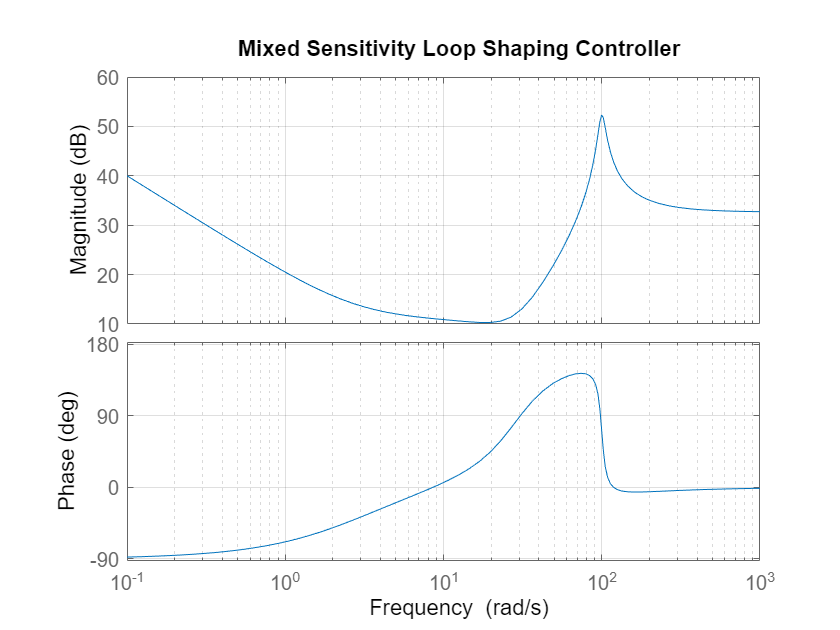

figure;
bode(Kx);
grid;
title("Mixed Sensitivity Loop Shaping Controller")

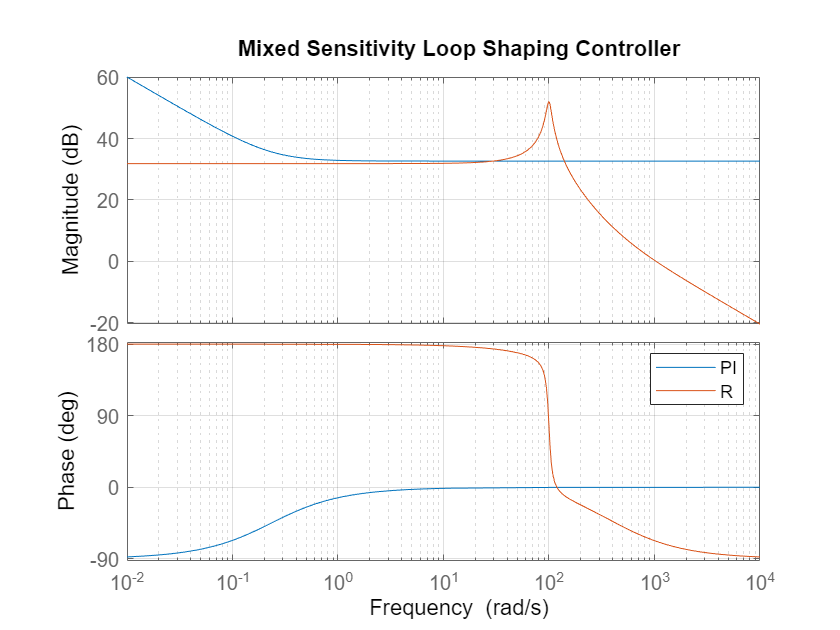

figure;
hold off
bode(K1);
hold on
bode(K2);
hold off
grid;
title("Mixed Sensitivity Loop Shaping Controller");
legend("PI","R");

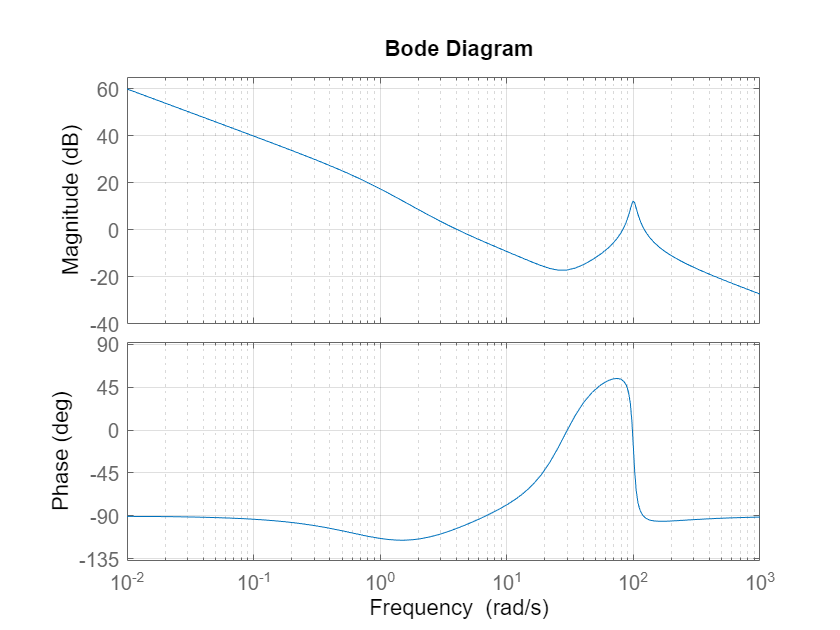

figure;
bode(Kx*P1);
grid;

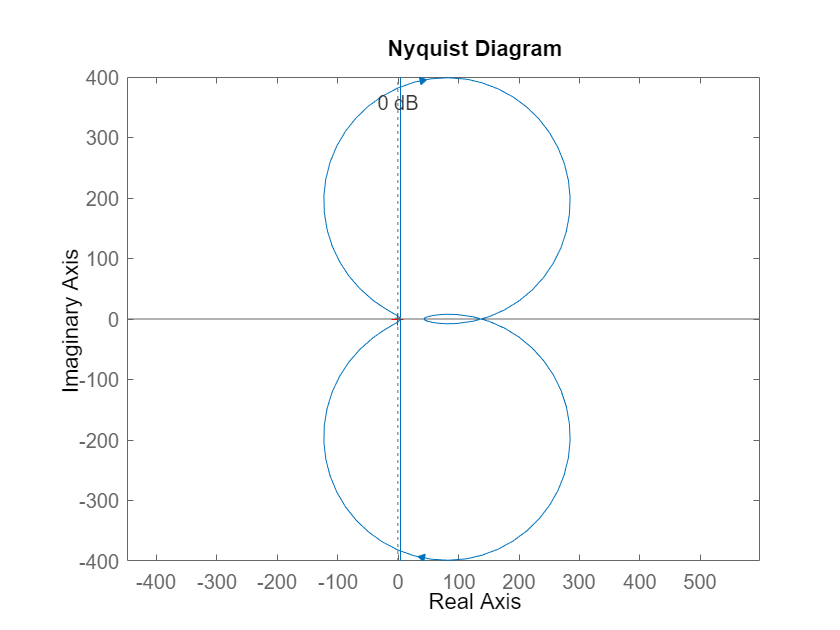

figure;
nyquist(Kx);
axis equal;
grid;

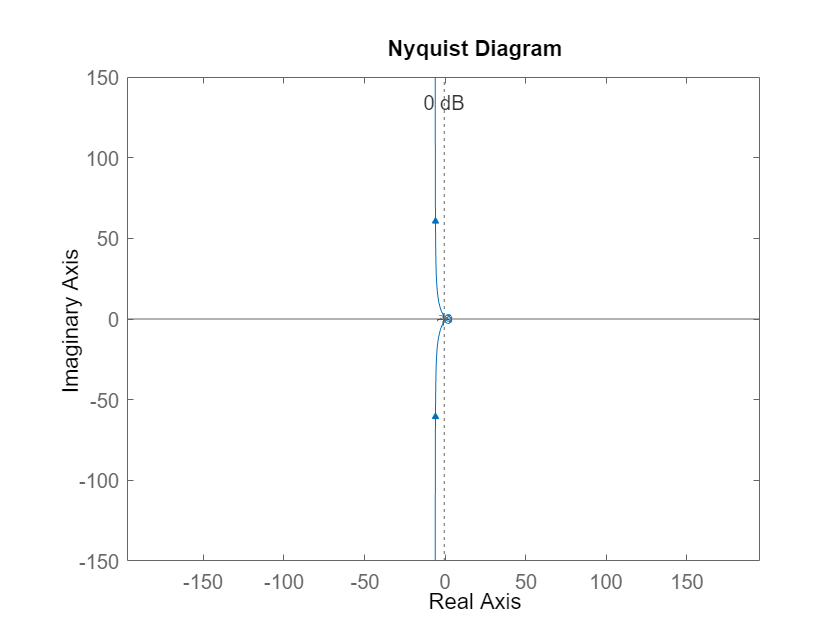

figure;
nyquist(Kx*P1);
axis equal;
grid;

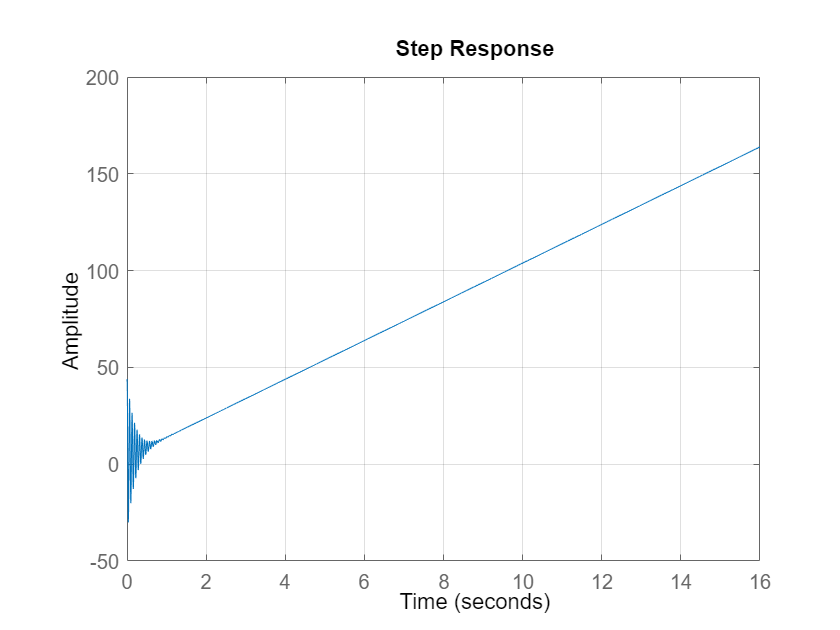

figure;
step(Kx);
grid;

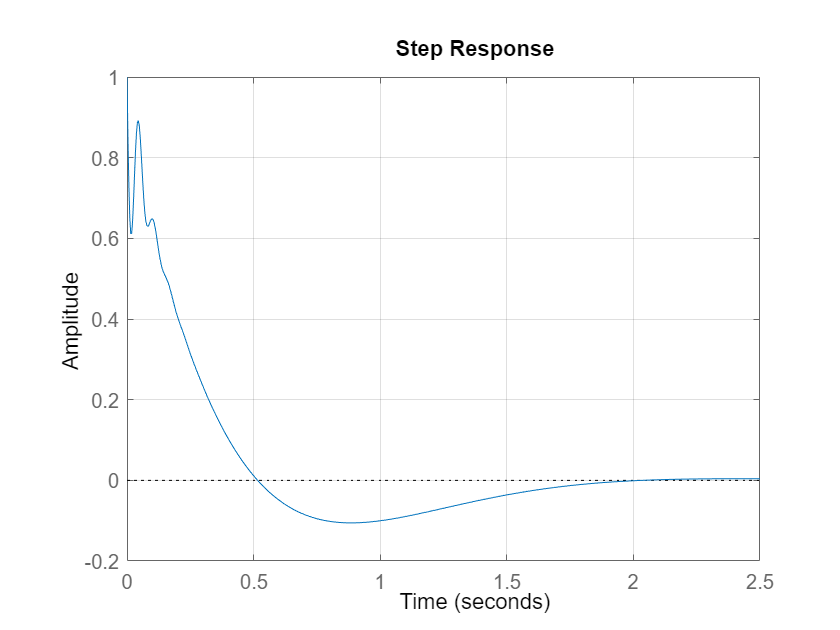

figure;
step(1/(1+Kx*P1));
grid;

function [S]=M2S(M)
    % convert linmod model to ss system
    S = ss(M.a,M.b,M.c,M.d);
end
